# Calculate the Correlation-Tetrac (detected event) and Pearson (ZF) correlation

               ** for all neuronal pairs or neuronal pair within the same cluster**

%identify current working folder
[root_path,animal_path,~] = fileparts(pwd); %pwd: display the current folder
animal_ID = split(animal_path, '_');
load ("./Modol_outputs/all.mat", 'C0','Race','start_time', 'end_time');  

**Define the time when mouse was whiskering and preparing data according to cluster**

%%Extract the ZF trace 
ZF_all = readmatrix ("Z_F.xlsx");
ZF = ZF_all(:,floor(start_time/0.0656):floor(end_time/0.0656) - 1);

%%Preparing Race/detected event and ZScore data according to the cluster
Race_cluster = cell(1,length(C0));
ZF_cluster = cell(1,length(C0));
for cluster_idx = 1:length(C0)        
    Race_cluster_temp = [];    
    ZF_cluster_temp = [];
    cluster_idx_cell_list_temp = C0{1,cluster_idx};
    
    for cell_idx = 1:length(cluster_idx_cell_list_temp)
        Race_cluster_temp(cell_idx,:) = Race(cluster_idx_cell_list_temp(1,cell_idx),:);
        ZF_cluster_temp(cell_idx,:) = ZF(cluster_idx_cell_list_temp(1,cell_idx),:);
    end
    
    Race_cluster{cluster_idx} = Race_cluster_temp;
    ZF_cluster{cluster_idx} = ZF_cluster_temp;
end

Plotting Race according to the cluster

% clf
% Race_fig = figure;
% subplot (length(C0)+1,1,1)
% imagesc(Race);
% title ('all neurons','Interpreter','none');
% 
% for cluster_idx = 1:length(C0)
%     subplot (length(C0)+1,1,cluster_idx+1)
%     imagesc(Race_cluster{cluster_idx});
%     title ('Race from neurons within the same cluster','Interpreter','none');
%     title (['Cluster is ', num2str(cluster_idx)],'Interpreter','none');
%     hold on 
% end
% sgtitle ('Detected events','Interpreter','none');

plotting ZScore trace according to the cluster

% clf
% ZF_trace = figure;
% subplot (length(C0)+1,1,1)
% plot(ZF');
% title ('all neurons','Interpreter','none');
% 
% for cluster_idx = 1:length(C0)
%     subplot (length(C0)+1,1,cluster_idx+1)
%     plot(ZF_cluster{cluster_idx}');
%     title (['Cluster is ', num2str(cluster_idx)],'Interpreter','none');
%     hold on 
% end
% sgtitle ('Z Score trace','Interpreter','none');

**Calculate tetrac correlation coefficient during spontaneous whisking**

%%Calculate tetrac R of all neuronal pairs
R_allpair = tetrac(Race');

View R: Inactivate this section when following the data analysis workfow;

% clf
% imagesc(R_allpair);
% colormap jet
% colorbar
% title ('Tetrac R')

%Sorting tetrac correlation results into list (single column)
R_allpair_tril = tril (R_allpair,-1);
R_allpair_flaten = nonzeros(R_allpair_tril);
R_allpair_mean = mean (R_allpair_flaten,'omitnan');

%%Calculate tetrac R of all neuronal pairs within the same cluster
%Pre-allocate array or matrix to store variables
Cluster_R = cell(1,length(C0));
Cluster_R_flaten = cell(1,length(C0));
Cluster_R_mean = nan(1,length(C0));
Cluster_R_all_column = [];

for idx = 1:length(C0)                          
    R = tetrac(Race_cluster{idx}');
    Cluster_R{idx} = R;
    R_tril = tril(Cluster_R{idx}, -1);
    R_flaten = nonzeros(R_tril(:));
    
    Cluster_R_flaten{idx} = R_flaten;
    Cluster_R_mean(:,idx) = mean(R_flaten);
    Cluster_R_all_column = vertcat(Cluster_R_all_column,R_flaten);
end
Cluster_R_all_mean = mean (Cluster_R_all_column,'omitnan');

Plotting to view R-distribution

% clf
% figure;
% bin_edge = [-0.6:0.1:1]; % defined edges-- minimum edge : bin size : max edge
% ytickValue = [0:0.25:1];
% 
% %plotting all neuronal pairs
% subplot(length(C0)+2,1,1)
% histogram (R_allpair_flaten,bin_edge,'normalization','cdf');
% xticks (bin_edge)
% yticks (ytickValue)
% title ('all pairs','Interpreter','none');
% hold on
% 
% %plotting neuronal pair in each cluster
% for idx = 1:length (C0)
%     subplot(length(C0)+2,1,1+idx)
%     histogram(Cluster_R_flaten{idx}, bin_edge,'normalization','cdf');
%     xticks (bin_edge)
%     yticks (ytickValue)
%     title (['Cluster is ', num2str(idx)],'Interpreter','none');
%     hold on     
% end
% 
% %plotting all neuronal pair in each cluster
% subplot(length(C0)+2,1,2+idx)
% histogram(Cluster_R_all_column, bin_edge,'normalization','cdf');
% xticks (bin_edge)
% yticks (ytickValue)
% title ('all pairs within the same cluster','Interpreter','none');
% 
% sgtitle ('Distribution of Tetrac Correlation coeff','Interpreter','none');

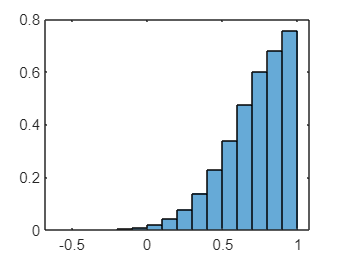

%%calculate R distribution
clf
bin_edge = [-0.6:0.1:1]; % defined edges-- minimum edge : bin size : max edge
R_allpair_Distri_Fig = histogram (R_allpair_flaten, bin_edge,'normalization','cdf');

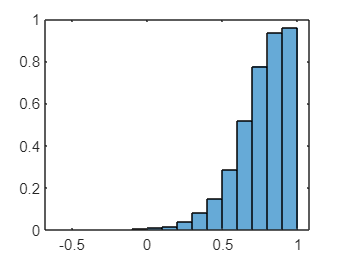

R_allpair_Distri = R_allpair_Distri_Fig.Values;

Cluster_R_Distri_Fig = histogram(Cluster_R_all_column, bin_edge,'normalization','cdf');

Cluster_R_Distri = Cluster_R_Distri_Fig.Values;

**Calculate Person correlation coefficient during spontaneous whisking**

%%Calculate Person R of all neuronal pairs
R_ZF_allpair = corrcoef (ZF','rows','pairwise');

View R: Inactivate this section when following the data analysis workfow;

% clf
% imagesc(R_ZF_allpair);
% colormap jet
% colorbar
% title ('Person R')

%Sorting Person correlation results into list (single column)
R_ZF_allpair_tril = tril (R_ZF_allpair,-1);
R_ZF_allpair_flaten = nonzeros(R_ZF_allpair_tril(:));
R_ZF_allpair_mean = mean (R_ZF_allpair_flaten,'omitnan');

%%Calculate Pearson Correlation of ZF
%Pre-allocate array and matrix to store variables
Cluster_R_ZF = cell(1,length(C0));
Cluster_R_ZF_flaten = cell(1,length(C0));
Cluster_R_ZF_mean = nan(1,length(C0));
Cluster_R_ZF_all_column = [];

for idx = 1:length(C0)                          
    R_ZF = corrcoef(Race_cluster{idx}','rows','pairwise');
    Cluster_R_ZF{idx} = R_ZF;
    R_ZF_tril = tril(Cluster_R_ZF{idx}, -1);
    R_ZF_flaten = nonzeros(R_ZF_tril(:));
    
    Cluster_R_ZF_flaten{idx} = R_ZF_flaten;
    Cluster_R_ZF_mean(:,idx) = mean(R_ZF_flaten);
    Cluster_R_ZF_all_column = vertcat(Cluster_R_ZF_all_column,R_flaten);
end
Cluster_R_ZF_all_mean = mean (Cluster_R_ZF_all_column,'omitnan');

Plotting to view whisking_cluster_R-distribution

% clf
% figure;
% 
% bin_edge = [-0.6:0.1:1]; % defined edges-- minimum edge : bin size : max edge
% ytickValue = [0:0.25:1];
% 
% %plot all neuronal pairs
% subplot(length(C0)+2,1,1)
% histogram (R_ZF_allpair_flaten,bin_edge,'normalization','cdf');
% xticks (bin_edge)
% yticks (ytickValue)
% title ('all pairs','Interpreter','none');
% hold on
% 
% %plot neuronal paris within each cluster
% 
% for idx = 1:length (C0)
%     subplot(length(C0)+2,1,1+idx)
%     histogram(Cluster_R_ZF_flaten{idx}, bin_edge,'normalization','cdf');
%     xticks (bin_edge)
%     yticks (ytickValue)
%     title (['Cluster is ', num2str(idx)],'Interpreter','none');
%     hold on     
% end
% 
% %plot all paris within the same cluster
% subplot(length(C0)+2,1,2+idx)
% histogram(Cluster_R_ZF_all_column, bin_edge,'normalization','cdf');
% xticks (bin_edge)
% yticks (ytickValue)
% title ('all pairs within the same cluster','Interpreter','none');
% 
% sgtitle ('Distribution of Person Correlation coeff','Interpreter','none');

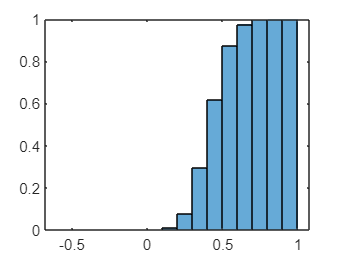

%%calculate Person R distribution
clf
bin_edge = [-0.6:0.1:1]; % defined edges-- minimum edge : bin size : max edge
R_ZF_allpair_Distri_Fig = histogram (R_ZF_allpair_flaten, bin_edge,'normalization','cdf');

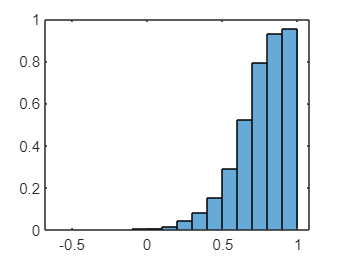

R_ZF_allpair_Distri = R_ZF_allpair_Distri_Fig.Values;

Cluster_R_ZF_Distri_Fig = histogram(Cluster_R_ZF_all_column, bin_edge,'normalization','cdf');

Cluster_R_ZF_Distri = Cluster_R_ZF_Distri_Fig.Values;

save ("./Modol_outputs/Correlation_inCluster.mat")